# Homework 8

Maxwell Greene

April 25th, 2018

## Problem 1(a):

## 
$$$f(t,x) = -\frac{x}{t}+\frac{1}{t}cos(t)$$$


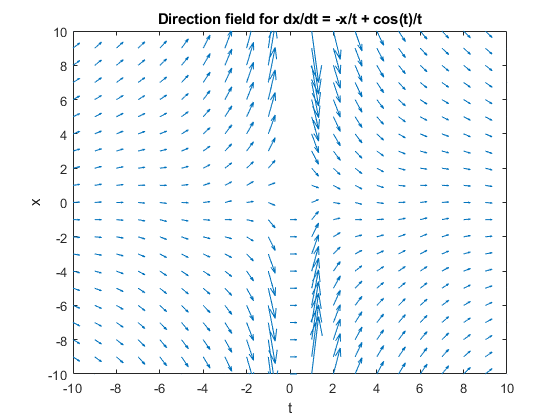

trange = linspace(-10,10,21);
xrange = linspace(-10,10,21);
[T,X] = meshgrid(trange,xrange);
dx = -(X./T) + cos(T)./T;
dt = ones(size(dx));

dx(isinf(dx)) = 0;

quiver(T,X,dt,dx,2.5)
xlabel('t')
ylabel('x')
axis([-10 10 -10 10])
title('Direction field for dx/dt = -x/t + cos(t)/t')

## Problem 1(b):

## 
$$(t_0,x_0) = (1,2)$$


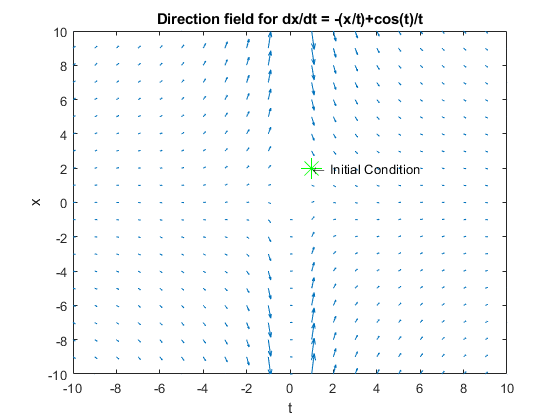

quiver(T,X,dt,dx);
xlabel('t')
ylabel('x')
axis([-10 10 -10 10])
title('Direction field for dx/dt = -(x/t)+cos(t)/t')
hold on
plot(1,2,'g*','MarkerSize',15)
txt1 = ['\leftarrow Initial Condition '];
text(1,2,txt1,'HorizontalAlignment','left')
hold off

## Problem 1(c):

f = @(t,x) -(x./t)+cos(t)./t;
tspan = [1 10];
x1 = 2;
[t, x] = ode45(f,tspan,x1);

## Problem 1(d):

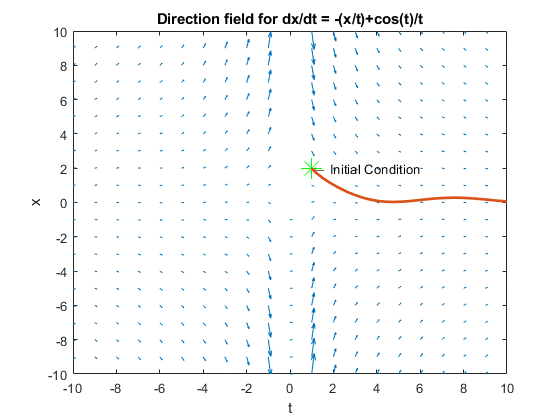

quiver(T,X,dt,dx)
xlabel('t')
ylabel('x')
axis([-10 10 -10 10])
title('Direction field for dx/dt = -(x/t)+cos(t)/t')
hold on
plot(1,2,'g*','MarkerSize',15)
txt1 = ['\leftarrow Initial Condition'];
text(1,2,txt1,'HorizontalAlignment','left')
plot(t,x,'LineWidth',2)
hold off